# Creating a Bland-Altman and Scatter Plot

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIOVASCULAR AND RESPIRATORY MONITORING DEVICES

The author would like to thank Dhrumil Naik for his assistance in developing this notebook.

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter1/BlandAltman'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Introduction

The **Bland-Altman plo**t and analysis is used to compare two measurements of the same variable. For example in bioinstrumentation, an expensive measurement system might be compared with a less expensive one or an intrusive measurement system might be compared  to a less intrusive one.

## Adding the Measurement Data 

For this example we are adding two measurement data from two different systems on the same variable. Suppose you want to evaluate the agreement between a continuous random variable (x1) and a second random variable (x2) which each measure the same variable, such as blood pressure. 

method_1 = [122 121 95 127 140 139 122 130 119 126 107   ...
    123	131	123	127	142	104	117	139	143	181	149	173 160	...
    158	139	153	138	228	190	103	131	131	126	121	97 116	...
    215	141	153	113	109	145	192	112	152	141	206	151 112	...
    162	117	119	136	112	120	117	194	167	173	228	77 154	...
    154	145	200	188	149	136	128	204	184	163	93 178 202	...
    162	227	133	202	158	124	114	137	121];

method_2 = [100 108 76 108 124 122 116 114 100 108 100 ... 
    108 112 104 106 122	100	118	140	150	166	148	174	174 ...
    140	128	146	146	220	208	94	114	126	124	110	90	106	218 ...
    130	136	100	100	124	164	100	136	114	148	160	84	156	110 ... 
    100	100	86	106	108	168	166	146	204	96	134	138	134	156 ...
    124	114	112	112	202	132	158	88	170	182	112	120	110	112	...
    154	116	108	106	122];
x = min(method_1):1:max(method_1);

This same data can be imported through a text file as well. Two columnns in this data set will be considered. 

a=load("BlandAltmanBPData.txt");
method1=a(:,8)';
method2=a(:,2)';
x1 = min(method1):1:max(method2);

##  Finding the Mean and Difference

The Bland-Altman plot  is formed by plotting the differences (x1 - x2) on the vertical axis versus the means [(x1+x2)/2] on the horizontal axis.

An array will be created for this mean and difference data, as well as the mean of differences, standard deviation of differences, and μ-2σ  and  μ +2σ. 

meanArray = mean([method1;method2]);
diffArray = method1-method2;
meanOfDiffs = mean(diffArray);
stdOfDiffs = std(diffArray);
confRange = [meanOfDiffs + 2.0 * stdOfDiffs, meanOfDiffs - 2.0 * stdOfDiffs];

##  Creating a Scatter Plot

Scatter plot visualizes paired observations in horizontal axis and  in vertical axis. In case of good agreement, we expect data to be scattered symmetrically around the 45 degree line.

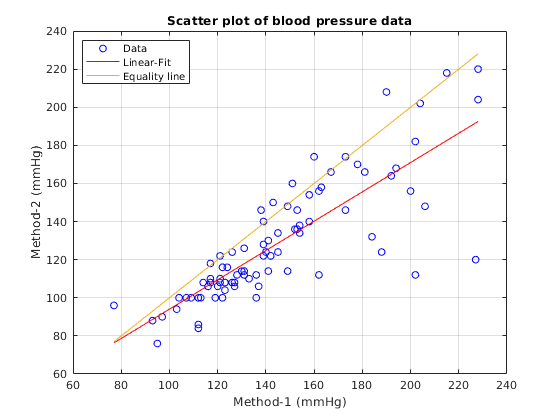

figure
[p,S] = polyfit(method1, method2, 1);
[yfit,delta] = polyval(p, method1, S); 
plot(method1, method2, 'bo');  % Plot method 1 and method 2 data
hold on;
plot(method1, yfit,'r-');
plot(x,x)
title("Scatter plot of blood pressure data")
legend('Data','Linear-Fit','Equality line', 'Location','northwest'); grid; 
xlabel('Method-1 (mmHg)'); ylabel('Method-2 (mmHg)')

annonation_save('a)',"Fig1.7a.jpg", SAVE_FLAG);

**What can you observe from this plot?**

The data points are mainly on one side of the 45 degree line. Data points are far from the equality line and also their trend is not parallel to the equality line. This indicates different proportional biases.

##  Creating a Bland-Altman Plot

Bland-Altman plot will show the average versus the difference. Both types of plots complement each other for the diagnosis of systematic and random errors. In a Bland-Altman plot, if there is a linear trend along average horizontal line, we can have two indications: (i) unequal proportional biases, or (ii) unequal precision. 

We would expect most of the differences to lie between μ-2σ  and  μ +2σ , or more precisely, 95% of differences will be between μ-1.96σ and μ +1,96σ, if the differences are normally distributed (Gaussian). These lines will be included to the plot. 

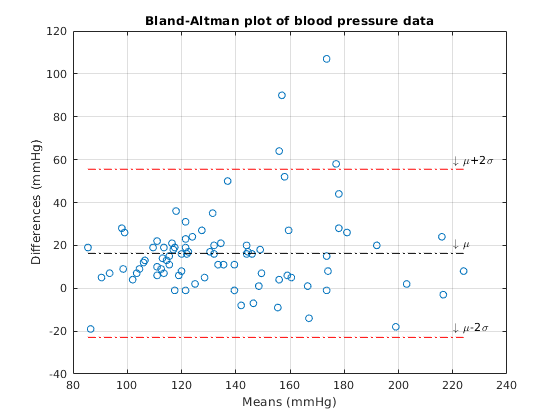

figure
plot(meanArray,diffArray,'o'); 
hold on;
line([min(meanArray) max(meanArray)],[confRange(1) confRange(1)],'Color','red','LineStyle','-.');
line([min(meanArray) max(meanArray)],[confRange(2) confRange(2)],'Color','red','LineStyle','-.');
line([min(meanArray) max(meanArray)],[meanOfDiffs meanOfDiffs],'Color','black','LineStyle','-.');
grid; ylabel('Differences (mmHg)'); xlabel('Means (mmHg)');
text(220,60,{'\downarrow \mu+2\sigma'})
text(220,21,{'\downarrow \mu'})
text(220,-18,{'\downarrow \mu-2\sigma'})
title("Bland-Altman plot of blood pressure data")
hold off;

annonation_save('b)',"Fig1.7b.jpg", SAVE_FLAG);

**What can you observe from this plot?**

The mean difference in methods is significant and it is 16.3 mmHg and standard deviation is 19.6 mmHg. We can see a number of outliers as well. In addition, it seems that data are scattered more with increased blood pressure indicating the effect of heteroscedasticity.

Heteroscedasticity refers to change of variance/scatter along the vertical direction as the average increases. It indicates the variability of  changes with magnitude of measurement. Reason for this is dependence of the error variation of one or both methods on the magnitude of measurement. In most of such cases, the Bland-Altman plot shows a fan shape which can be observed in the created plot. 

## Exercise 

**Exercise**: Create a Bland-Altman plot for other pairs of data from the blood pressure dataset provided.

Use sliders to select different measurements, please select measurements that are pairs. For example Columns 8&2, 9&3 or 10&4.


a=load("BlandAltmanBPData.txt");

Column1 =8

Column1 = 8

Column2 =4

Column2 = 4


method10=a(:,Column1)';
method20=a(:,Column2)';
x10 = min(method10):1:max(method20);


 Finding the Mean and Difference


meanArray1 = mean([method10;method20]);
diffArray1 = method10-method20;
meanOfDiffs1 = mean(diffArray1);
stdOfDiffs1 = std(diffArray1);
confRange1 = [meanOfDiffs1 + 2.0 * stdOfDiffs1, meanOfDiffs1 - 2.0 * stdOfDiffs1];



 Creating a Scatter Plot

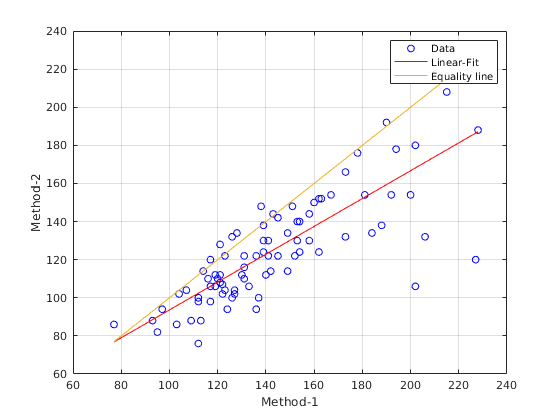

figure
[p,S] = polyfit(method10, method20, 1);
[yfit,delta] = polyval(p, method10, S); 
plot(method10, method20, 'bo');  % Plot method 1 and method 2 data
hold on;
plot(method10, yfit,'r-');
plot(x,x)
legend('Data','Linear-Fit','Equality line'); grid; 
xlabel('Method-1'); ylabel('Method-2')

 Creating a Bland-Altman Plot

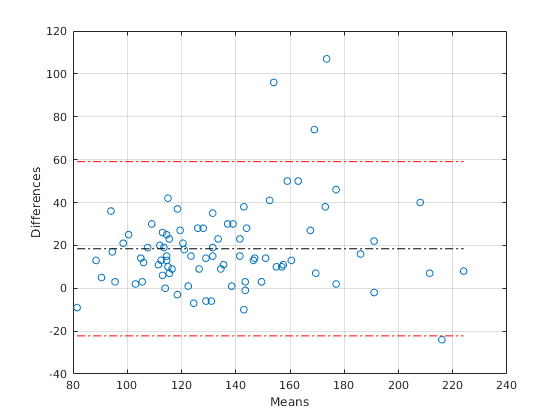

figure
plot(meanArray1,diffArray1,'o'); 
hold on;
line([min(meanArray1) max(meanArray1)],[confRange1(1) confRange1(1)],'Color','red','LineStyle','-.');
line([min(meanArray1) max(meanArray1)],[confRange1(2) confRange1(2)],'Color','red','LineStyle','-.');
line([min(meanArray1) max(meanArray1)],[meanOfDiffs1 meanOfDiffs1],'Color','black','LineStyle','-.');
grid; ylabel('Differences'); xlabel('Means');
hold off;